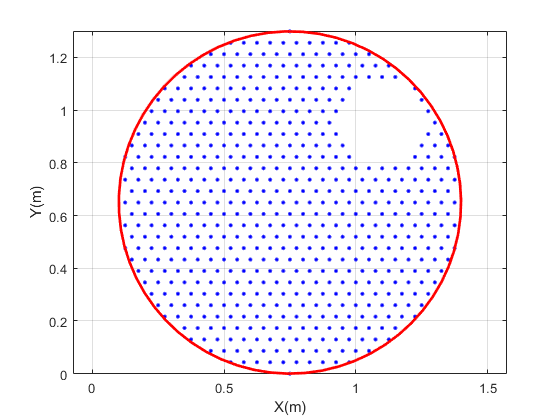

clear all;
close all;
clc;

tic

f0=3e9;
c=3e8;
lambda=c/f0; 
dx=lambda/2;
dy=dx/2*3^(0.5);
k=2*pi/lambda;

phi=0*pi/180;%目标方位角
theta=0*pi/180;%目标俯仰角

theta1=sin(phi)*cos(theta);
theta2=sin(theta);
N1=30;
N2=30;
X1=[0:(N1-1)]*dx;
X11=[0:(N1-1)]*dx+dx/2;
X=[X1,X11];
Y=[0:(2*N2-1)]*dy;




X2=kron(ones(1,N2),X);
Y2=kron(Y,ones(1,N1));

x0=N1/2*dx;
y0=N2/2*dy;
r=y0;
[~,n]=size(X2);
index=1;
%去掉圆1外的天线
while(index<=n)
    l=((X2(index)-x0)^2+(Y2(index)-y0)^2)^(0.5);
    if l>r
        X2=dele(X2,index);
        Y2=dele(Y2,index);
        n=n-1;
        index=index-1;
    end
    index=index+1;
end
%去掉圆2内的天线
x1=N1/2*dx+floor(N1/4)*dx;
y1=N2/2*dy+floor(N2/4)*dy;
r1=y0/4;

[~,n]=size(X2);
index=1;
while(index<=n)
    l=((X2(index)-x1)^2+(Y2(index)-y1)^2)^(0.5);
    if l<r1
        X2=dele(X2,index);
        Y2=dele(Y2,index);
        n=n-1;
        index=index-1;
    end
    index=index+1;
end
%绘图
t=0:0.1:2.1*pi;
x=x0+r*cos(t);
y=y0+r*sin(t);

figure
plot(X2,Y2,'b.','markersize',8);
hold on
plot(x,y,'r','linewidth',2);
axis equal;
grid on;
xlabel('X(m)');
ylabel('Y(m)');

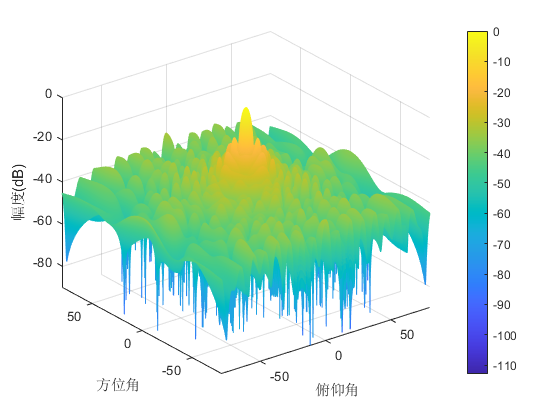

steer_signal1=exp(1j*k*X2*theta1);
steer_signal2=exp(1j*(k*Y2*theta2));
steer_signal3=steer_signal1.*steer_signal2;
normal_W=steer_signal3;
%合成方向图
Theta =-80:0.1:80;
Phi =-80:0.1:80;
m = length (Theta);
n = length (Phi);
Fm = zeros (m,n);
for m =1:length(Theta)
    for n =1:length(Phi)
         theta =Theta(m); 
         phi = Phi(n);
         phase1 = exp(1j*k*X2*sin(theta*pi/180)*cos(phi*pi/180));
         phase2 = exp(1j*k*Y2*sin(phi*pi/180));
         phase_all = (phase1.*phase2).';
         Fm(m,n)=abs(((normal_W.')')*phase_all);
    end
end
FdBm =20*log10(Fm/max(max(Fm)));%画增益图
figure 
mesh(Phi,Theta,FdBm); 
colorbar 
xlabel ('俯仰角'); 
ylabel ('方位角'); 
zlabel ('幅度(dB)'); 
axis ([-80 80 -80 80 -90 0]);

%未缺失
X1=[0:(N1-1)]*dx;
X11=[0:(N1-1)]*dx+dx/2;
X=[X1,X11];
Y=[0:(2*N2-1)]*dy;

X2=kron(ones(1,N2),X);
Y2=kron(Y,ones(1,N1));

x0=N1/2*dx;
y0=N2/2*dy;
r=y0;
[~,n]=size(X2);
index=1;
while(index<=n)
    l=((X2(index)-x0)^2+(Y2(index)-y0)^2)^(0.5);
    if l>r
        X2=dele(X2,index);
        Y2=dele(Y2,index);
        n=n-1;
        index=index-1;
    end
    index=index+1;
end

steer_signal1=exp(1j*k*X2*theta1);
steer_signal2=exp(1j*(k*Y2*theta2));
steer_signal3=steer_signal1.*steer_signal2;
normal_W=steer_signal3;
%合成方向图
Theta =-80:0.1:80;
Phi =-80:0.1:80;
m = length (Theta);
n = length (Phi);
F = zeros (m,n);
for m =1:length(Theta)
    for n =1:length(Phi)
         theta =Theta(m); 
         phi = Phi(n);
         phase1 = exp(1j*k*X2*sin(theta*pi/180)*cos(phi*pi/180));
         phase2 = exp(1j*k*Y2*sin(phi*pi/180));
         phase_all = (phase1.*phase2).';
         F(m,n)=abs(((normal_W.')')*phase_all);
    end
end
FdB =20*log10(F/max(max(F)));%画增益图
figure 
mesh(Phi,Theta,FdBm); 
colorbar 
xlabel ('俯仰角'); 
ylabel ('方位角'); 
zlabel ('幅度(dB)'); 
axis ([-80 80 -80 80 -90 0]);

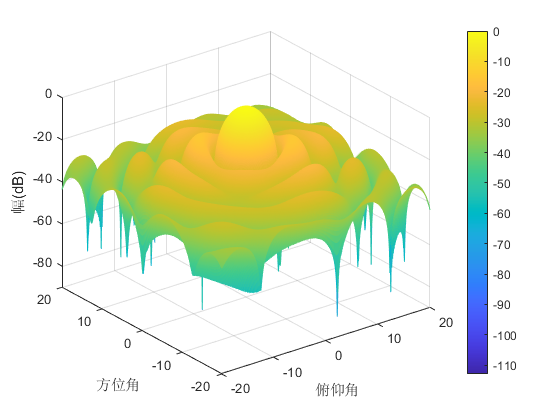


%画增益图放大
figure
mesh (Phi, Theta, FdBm) ;
xlabel('俯仰角');ylabel( '方位角');zlabel( '幅(dB)');
  axis([-20 20 -20 20 -90 0]);
colorbar

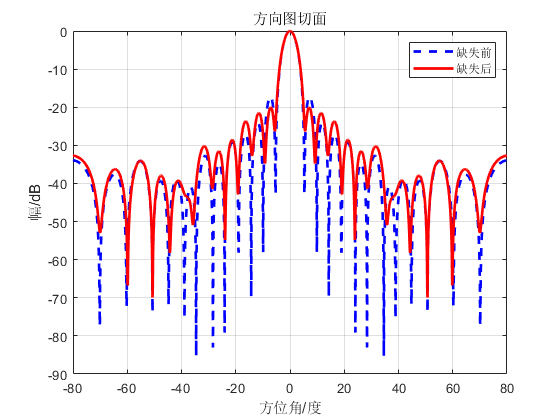

%画方位增益图
[ymaxm, iym]=max(max(FdBm)); 
[ymax, iy]=max(max(FdB)); 
figure
plot (Theta,FdB(:,iy),'b--','linewidth',2);title('方向图切面');
hold on
plot (Theta,FdBm(:,iym),'r','linewidth',2);
xlabel('方位角/度');ylabel( '幅/dB')
legend('缺失前','缺失后');
grid on;
hold on

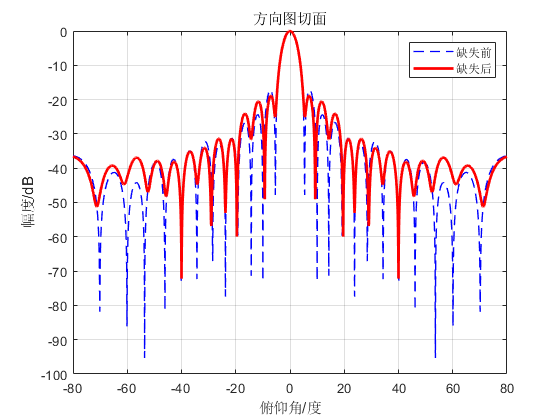

%画俯仰增益图
[xmaxm,ixm]=max(FdBm(:,iy));
[xmax,ix]=max(FdB(:,iy));
figure
plot(Phi,FdB(ix, :),'b--','linewidth',1);title('方向图切面');
hold on
plot(Phi,FdBm(ixm, :),'r','linewidth',2);
legend('缺失前','缺失后');
xlabel( '俯仰角/度');ylabel( '幅度/dB');grid on;hold on;

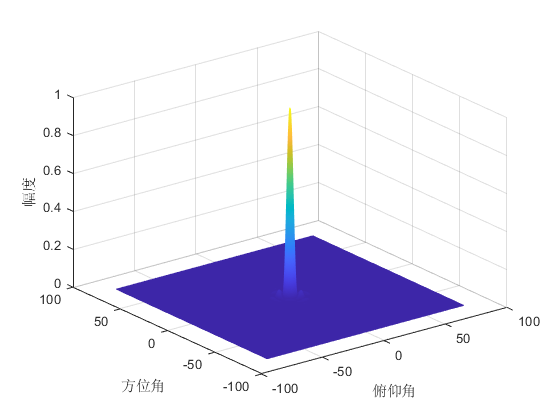

%画方位原始数值增益
figure
mesh(Phi, Theta, 10.^(FdBm/10));
xlabel( '俯仰角');ylabel( '方位角');zlabel( '幅度')

toc

历时 178.524211 秒。
